# Numerical Methods for Engineers

Due Date: 22nd Feb. 2024

Student Name: Marc-Antoine Nadeau

## Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

## Please submit this **.mlx** file along with the **PDF** copy of this file.

## Question 1: Cholesky Least Squares Estimation **(10 marks)**

(a) **Cholesky factorization **is an alternative to LU decompostion which can be applied on symmetric positive definite matrices. A symmetric positive definite matrix$\mathit{\mathbf{M}}$must satisfy following two conditions:

     1. The matrix $\mathit{\mathbf{M}}$must be symmetric, i.e. $\mathit{\mathbf{M}}={\mathit{\mathbf{M}}}^{\mathit{\mathbf{T}}}$

     2. The matrix $\mathit{\mathbf{M}}$ must be positive definite,  i.e.  ${\mathit{\mathbf{x}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{M}}\;\mathit{\mathbf{x}}>0$ for  all  $\mathit{\mathbf{x}}\in \Re^{N\times 1}$, $\left\|\mathit{\mathbf{x}}\right\|\not= 0$.

If the above two conditons are met then the matrix $\mathit{\mathbf{M}}$ can be factored as 


$$\mathit{\mathbf{M}}={\mathit{\mathbf{U}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{U}}$$
                 

where $U$ is a $N\times N$the lower upper matrix with real and positive diagonal enteries. The enteries of matrix $U$ are given by the following expression 


$$\textbf{U}_{i,j} = 
\begin{cases}
    \sqrt{ \textbf{M}_{i,i} - u_i(1:i-1)^Tu_i(1:i-1) }    ,& \text{if  } i =j\\
    \frac{1}{\textbf{U}_{i,i}} \left(\textbf{M}_{i,j} - u_i(1:i-1)^Tu_j(i:i-1) \right),              & \text{if  } i<j\\
0, & \text{otherwise}
\end{cases}$$


The cost of Cholesky factorization algorithm is rougly half than the LU decompostion. Your task is to implement the Cholesky decomposition alogorithm, the use the outline of the function named *CholeskyDecomposition* provided in the appendix.

Use the cell below to test your Cholesky decompostion code by computing the Frobenius norm of  $\left.{\mathit{\mathbf{U}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{U}}-M\right)\ldotp$

M= [2 -1 0; -1 2 -1; 0 -1 2];
U = CholeskyDecompositon(M);
Error =  norm(U'*U-M)

Error = 4.4409e-16

 b) In regression problems we ofthen need to solve the normal eqautions,  ${\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\;\mathit{\mathbf{x}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$.  Show that the matrix $\left({\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\right)$ is symmetric positive definite, and thus can be factored using Cholesky Decomposition.

- **Symetric**: 

- 
$$\textrm{We}\;\textrm{know}\;\textrm{that}\;\textrm{for}\;a\;\textrm{matrix}\;\textrm{to}\;\textrm{be}\;\textrm{symetric}\;\textrm{it}\;\textrm{must}\;\textrm{sastify}\;A=A^T$$


- 
$${\left(A^T A\right)}^T =A^{T\;} {\left(A^T \right)}^T =A^T A$$


- Thus, we conclude that it is a symmetric matrix.

- **Positive Definite:**

- A matrix M is said to be positive definite if $x^T \textrm{Mx}>0\;\textrm{for}\;\textrm{all}\;\mathit{\mathbf{x}}\in \Re^{N\times 1} ,\;\left\|\mathit{\mathbf{x}}\right\|\not= 0\;$

- 
$$x^T \left(A^T A\right)x=x^T A^T \textrm{Ax}={\left(\textrm{Ax}\right)}^T \left(\textrm{Ax}\right)=||\;\textrm{Ax}||_2^2 >0$$


- Thus, we conclude that it is a Positve Definite matrix

c) Using Cholesky facotrization scheme $\left({\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\right)$ can be factored as ${\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\;={{\mathit{\mathbf{U}}}^{\mathit{\mathbf{T}}} }^{\;} \mathit{\mathbf{U}}$. This transforms the normal equation into the form,


$${\mathit{\mathbf{U}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{U}}\;\mathit{\mathbf{x}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$$


The above equation consists of the triangular systems. The solution **x **can be obtained by  first solving ${\mathit{\mathbf{U}}}^T \;\mathit{\mathbf{y}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$ using the forward substitution, then by solving the  $\mathit{\mathbf{U}}\;\mathit{\mathbf{x}}=\mathit{\mathbf{y}}$ using backward subsitution. Implement the Cholesky solver function named *LeastSquareSolver_Cholesky  *for least squares in the function in the appendix.

Test the your Cholesky Least Square solver below.

A = rand(30,15); % random over-determined system
b = ones(30,1);
norm(A)

ans = 11.1513


x = LeastSquareSolver_Cholesky(A,b)

x =    -9.5938
   -9.7041
   -7.7174
  -14.8100
   -2.7353
    0.8373
    1.0042
    7.9761
    1.6951
   -3.2532




x_matlab = A \ b;

residual = A*x-b

residual =    -7.2306
    1.5970
   -5.5464
   11.5207
    3.2628
   10.0514
    0.5138
   -6.3557
    6.0640
    5.1792



residual_matlab = A * x_matlab - b

residual_matlab =    -0.1028
   -0.0235
    0.0413
    0.0839
    0.0399
   -0.0607
   -0.0788
    0.0070
   -0.0002
    0.0735



Norm_residual = norm(residual);

norm_residual_matlab = norm(residual_matlab);

disp(['Question 1c: The norm of the residual after solving using Cholesky based least sqaure solver is '  num2str(Norm_residual)]);

Question 1c: The norm of the residual after solving using Cholesky based least sqaure solver is 39.8302


## Question 2: Proofs **(10 marks)**

a) Show that the condition number of $A^TA$ is $\kappa \;\left(A^{T\;} A\right)={\kappa \left(A\right)}^2 \;$.

*SEE PDF*

b) Given two orthonormal matrices $U$and $Q$, show that product of these matrices, $\textrm{UQ}$, is also orthonormal.

*SEE PDF*

c) If A is an invertible matrix and Q is an orthonormal matrix, show that $\kappa \left(\textrm{QA}\right)=\kappa \left(A\right)\ldotp$

*SEE PDF*

## Question 3:  QR Decomposition **(10 marks)**

 In this question we will develop the different algorithms to implement QR factorization.

a)  Use the cell below to implement a function that computes Gram-Schmidt based QR decompositon of a input matrix A.

  Use the cell below to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB, comment on your result.

   A = rand(15,6); % A is a 15x6 matrix of random numbers
   [Qgs,Rgs] = gschmidt(A);
   
   %use the norm to check 
   normGS = norm(A-Qgs*Rgs,'fro') ;
   disp(normGS)

   3.2376e-16



- Using the Frobenius norm provides a measure of the overall magnitude of the differences between the two matrices. In our case, the Frobenius norm computes a difference on the order of $2\times {10}^{-16} \;\textrm{to}\;4\times {10}^{-16}$. Such a low norm suggests that our implementation of the Gram-Schmidt QR decomposition is extremely close to the actual value of *A*.

b)  Use the cell below to implement a function that uses the Modiefied Gram-Schmidt approach to compute the  QR decompositon of  the input matrix A.

  Use the cell below to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB, comment on your result.

   A = rand(15,6); % A is a 15x6 matrix of random numbers
   [Qmgs,Rmgs] = mgschmidt(A);
   
   normMGS = norm(A-Qmgs*Rmgs,'fro');
   disp(normMGS)

   3.4093e-16



- Using the Frobenius norm provides a measure of the overall magnitude of the differences between the two matrices. In our case, the Frobenius norm computes a difference on the order of $2\times {10}^{-16} \;\textrm{to}\;4\times {10}^{-16}$. Such a low norm suggests that our implementation of the Modified-Gram-Schmidt QR decomposition is extremely close to the actual value of *A*.

## **Question 4:  Polynomial Fitting using Least Squares Estimation  (10 marks)**

Polynomial fitting is one of the many applications of Least-Squares Approximation. Given the experimental data, shown in Table below, 

    
$$\matrix{   Input,, x  | &  x_0  &x_1  & x_2& x_3 &\dots  & x_{m-1}& x_m \cr
Output, y| &  y_0 & y_1& y_2 & y_3 & \dots & y_{m-1}&y_m
}$$


we can fit a $n^{\textrm{th}}$degree polynomial, $p\left(x\right)=a_0 +a_1 x+a_{2\;} x^{2\;} +a_3 x^3 +\cdots +a_{n\;} x^n$. To find the coefficicients,  $\mathit{\mathbf{a}}=\left\lbrack a_{0\;} ,\;\;a_1 ,\;\;a_2 ,\cdots a_n \right\rbrack$, we can solve the linear system shown below. 


$$\underset{\mathit{\mathbf{M}}}{\underbrace{\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
1 & x_{2\;}  & x_{2\;}^2  & \cdots \; & x_{2\;}^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_{m-1}  & x_{m-1}^2  & \cdots  & x_{m-1}^n \\
1 & x_m  & x_m^2  & \cdots \; & x_m^n 
\end{array}\right\rbrack } }$$

$$\underset{\mathit{\mathbf{a}}}{\underbrace{\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\vdots \\
a_n 
\end{array}\right\rbrack } } =\underset{\mathit{\mathbf{Y}}}{\underbrace{\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
\vdots \\
y_{m-1} \\
y_m 
\end{array}\right\rbrack } }$$


The system $\mathit{\mathbf{M}}\;\mathit{\mathbf{a}}=\mathit{\mathbf{Y}}$ can then be solved to compute the coefficients in vector $\mathit{\mathbf{a}}\ldotp$

a) Your first task is to write a function that takes the input data vector $\mathit{\mathbf{x}}$ and degree of the polynomial, then returns the polynomial matrix $\mathit{\mathbf{M}}\ldotp$ Complete the function *PolynomialMatrix* in the appendix.

% test your code here by inputing X= [ 1 2 3] for degree 3. 

% You can manually verify if this matrix is implemented correctly.

X= [1; 2; 3];
Mtest = PolynomialMatrix(X,3)

Mtest =      1     1     1     1
     1     2     4     8
     1     3     9    27


b) The least squares method can be used to solve the overdetermined linear system $\mathit{\mathbf{M}}\;\mathit{\mathbf{a}}=\mathit{\mathbf{Y}}$ to obtain the polynomial coefficients. This can be done by directly solving the Normal equations (using cholesky decomposition for example) or by using QR decomposition. In the code below, use the **MATALB's QR decomposition function** to find the polynomial coefficients if we assume a polynomial model of order 1. 

% Load the Input Data from the provided .mat file 
load('/Users/marc-antoinenadeau/Desktop/4th Semester/ECSE 343/Assignments/A2/Polynomial_Fitting_Data.mat');

x = x_given;
y = y_given;
deg = 1;

% get Polynomial Matrix 
Mp = PolynomialMatrix(x,deg);


   
% MATLAB QR Decomposition
[Q,R] = qr(Mp,0);%Changed Mp for M
   
% Find the polynomial coefficients using Q & R matrices obtained above.
% For forward and backward substitution functions use the forward
% substitution and the backward substitution you wrote in Assignment 1
  
   
% Name the Coefficeints obtained QR as Ar
Ar = backward_sub(R,Q'*y) 

Ar =    -2.1670
   -3.7257


Now that you have obtained the coefficients for the first order polynomial model, $p\left(x\right)=a_0 +a_1 x$, we can test this model by evaluating $p\left(x\right)$ at different values of $x$ between 0 to 7. **Run the code below and explain the results obtained in the figure. Is this order sufficient?**

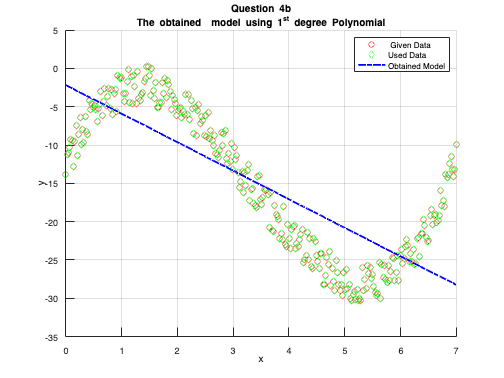

   xtest = x;
   
   px = zeros(length(xtest),1);
   powers = 0:deg;
   for I = 1:length(powers)
       px = px + Ar(I)*xtest.^powers(I);   
   end
   %plots
    figure
   hold on
   plot(x,y,'ro')
 plot(x,y,'gd')
   plot(xtest,px,'b-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   legend(' Given Data','Used Data','Obtained Model')
   grid on
   title({'Question 4b';'The obtained  model using 1^{st} degree Polynomial'})

- Based on the figure above, we observe that the order is not appropriate to match the data points. Namely, we have almost sinusoidal data points, yet our model is linear (i.e., of degree 1).  As such, the linear model is underfitting even if we use all the data points in the system. The linear model would be more appropriate with a different intercept and slope for x values in the range of 1.5 to 5.

c) In this part we will use a higher order model (a polynomial of order 6), but only a limited amount of input data points to generate this model (we will use only** 15 data points)**. Use QR decomposition function to find the polynomial coefficients for the **6th degree polynomial**.  

% Load the Input Data from the provided .mat file 

load('/Users/marc-antoinenadeau/Desktop/4th Semester/ECSE 343/Assignments/A2/Polynomial_Fitting_Data.mat');

deg = 6; %polynomial degree
x = x_given(1:20:end);  % x has 15 data points!! 
y = y_given(1:20:end);  % y has 15 data points!!

% get Polynomial Matrix 
Mp= PolynomialMatrix(x,deg);


   % MATLAB QR Decomposition
   %[Q,R] = qr(Mp)
   [Q,R] = qr(Mp);
   
   %--------------------------------------------------------------------------------------------------
   % Find the polynomial coefficients using  Q & R matrices obtained obove.
   
   
   
   % Name the Coefficeints obtained QR as Ar
            
   Ar = backward_sub(R,Q'*y)

Ar =   -14.0832
   35.0494
  -34.3004
   15.5398
   -3.8678
    0.4798
   -0.0227


We can test this model by evaluating $p\left(x\right)=a_{0\;} +a_1 x+\ldotp \ldotp \ldotp +a_6 x^6$ at different values of $x$ between 0 to 7. **Is this a good model? Comment on the results obtained in figure Question 5c, and explain the cause of what you see.**

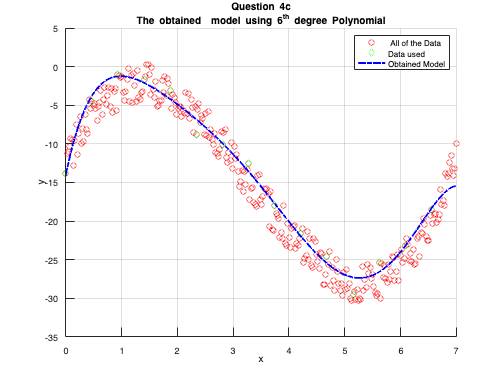


   xtest = linspace(0,7,701);
   xtest = xtest';
   powers = 0:deg;
   px = zeros(length(xtest),1);
 
   for I = 1:length(powers)
       px = px + Ar(I)*xtest.^powers(I);   
      
   end
   %plots
   figure
   hold on
   plot(x_given,y_given,'ro') % plot all Data
   plot(x,y,'gd') % plot Used Data
   plot(xtest,px,'b-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   legend(' All of the Data','Data used','Obtained Model')
   title({'Question 4c';'The obtained  model using 6^{th} degree Polynomial'})
   grid on

- Despite the utilization of only 15 data points within a higher-degree (i.e., degree 6) of the mdoel such that $p\left(x\right)=a_{0\;} +a_1 x+\ldotp \ldotp \ldotp +a_6 x^6$ the fitting closely approximates the data points, exhibiting a near-perfect alignment. Specifically, the model accurately captures the sinusoidal nature of the data points within the designated segment, ranging from 0 to 7.

d ) In this part we will use a polynomial of order **14,**  again this will be used with limited amount of data (we will use only** 15 data points, same as part c**). Use QR decomposition function to find the polynomial coefficients for the **14th degree polynomial**.  

% Load the Input Data from the provided .mat file 

load('/Users/marc-antoinenadeau/Desktop/4th Semester/ECSE 343/Assignments/A2/Polynomial_Fitting_Data.mat');

deg =14;
x = x_given(1:20:end);  % x has 15 data points!! 
y = y_given(1:20:end);  % y has 15 data points!!

% get Polynomial Matrix 
Mp= PolynomialMatrix(x,deg);


   % MATLAB QR Decomposition
   %[Q,R] = qr(Mp)
   [Q,R] = qr(Mp);
   
   %--------------------------------------------------------------------------------------------------
   % Find the polynomial coefficients using  Q & R matrices obtained obove.
   
   
   
   % Name the Coefficeints obtained QR as Ar
            
   Ar = backward_sub(R,Q'*y);

We can test this model by evaluating $p\left(x\right)$ at different values of $x$ between 0 to 7. **Is this a good model? Comment on the results obtained in figure Question 5d, and explain the cause of what you see.**

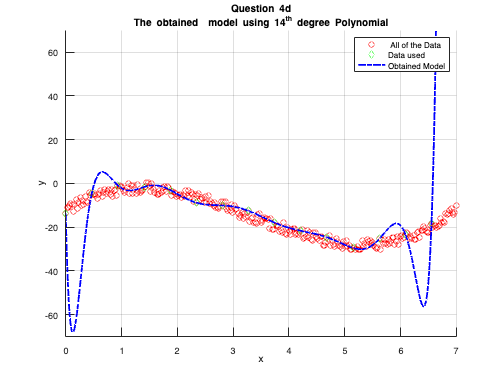


   xtest = linspace(0,7,701);
   xtest = xtest';
   powers = 0:deg;
   px = zeros(length(xtest),1);
 
   for I = 1:length(powers)
       px = px + Ar(I)*xtest.^powers(I);   
      
   end
   %plots
   figure('Name','Question 4d','NumberTitle','off')
   hold on
   plot(x_given,y_given,'ro') % plot all Data
   plot(x,y,'gd') % plot Used Data
   plot(xtest,px,'b-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   ylim([-70,70])
   legend(' All of the Data','Data used','Obtained Model')
 title({'Question 4d';'The obtained  model using 14^{th} degree Polynomial'})
   grid on 

- In this model, we utilize a polynomial of degree 14 such that $p\left(x\right)=a_{0\;} +a_1 x+\ldotp \ldotp \ldotp +a_{14} x^{14}$ with only 15 data points. Although the model passes through all 15 points used for its development, it is evident that the model is overfitting the data. Overfitting occurs when a model fits the training data too closely, failing to capture the underlying pattern of the data points. The combination of a small sample size and a high degree of the model leads to overshooting/undershooting at the extremes (i.e. from x in the range 0 to 1 and 6 to 7) and overfitting phenomenon in the middle (from x in the range 1 to 6) . Consequently, the model fails to accurately capture the sinusoidal shape of the data.

## Appendix 

## * Implement the Cholesky Decompositon fucntion here.*

function U =  CholeskyDecompositon(M)
if(size(M,1) ~= size(M,2))
    disp('Matrix M must be square!');
end
    U = zeros(size(M));
    [n,m] = size(M); %get size of matrix M
    for i = 1:n
        for j = 1:m % fixed loop range to only consider elements above or on the diagonal
            if i == j
                U(i,j) = sqrt( M(i,i) - U(1:i-1,i)'*U(1:i-1,i) );
            elseif i < j
                U(i,j) = ( M(i,j) - U(1:i-1,i)'*U(1:i-1,j) ) / U(i,i);
            end
        end
    end
end


## *Implement Least Square Solver for Cholesky here*

function x = LeastSquareSolver_Cholesky(A,b)
% get M = A^T A
M = A'*A;

% write your code here
% Step 1. Call the choesky function written in part (a) to get Lower triangular matrix,L
   % M = L L^T
L = CholeskyDecompositon(M);

% Step 2. Use the forward substitution function named  ForwardSubs() provided in the appendix

y = forward_sub(L,A'*b);
       
% Step 3. Use the backward substitution function BackwardSubs() proivded in the appendixh--
x = backward_sub(L, y);

end

## *Forward Sub*

function y = forward_sub(L,b)
% y is the vector - Here we let Ux = y to solve for LUx = b  
% L is the lower triangular matrix
% Ly = b --> solve with forward sub

    n = length(b); 
    y = zeros(n, 1);
    for i = 1:n 
        y(i) = ( b(i) - L(i, 1:i-1) * y(1:i-1) ) / L(i,i);
    end
end 


## *Backward Sub*

function X = backward_sub(U,y)
% X is the vector
% U is the upper triangular matrix
% Ux = y --> solve with backward sub
    [~, n] = size(U);
    X = zeros(n, 1);
    for i = n:-1:1
        if i == n
            X(i) = y(i) / U(i, i);
        else
            X(i) = (y(i) - U(i, i+1:n) * X(i+1:n)) / U(i, i);
        end 
    end
end

## *Implement Polynomial Matrix here *

function M = PolynomialMatrix(x,n)
% write your code here
% n is the degree of the polynomil
% x is the vector of input data
m = length(x);
M = zeros(m, n+1);

% Construct the polynomial matrix
for i = 1:m
    for j = 1:(n+1)
        M(i, j) = x(i)^(j-1);
    end
end

end


## *Implement QR Methods here*

- *Classical GramSchmidt *

function [Q,R] = gschmidt(A)
   % A is the input matrix- 
   % A could be a overdetermined matrix or a square matrix
   % Q is orthonormal matrix 
   % R is the upper triangular matrix 

   % This implementation is the Economy-Size Version
   [m,n] = size(A);
   Q = zeros(m, n);
   R = zeros(n, n);

   R(1, 1) = norm(A(:, 1));
   Q(:, 1) = A(:, 1) / R(1, 1);

   for j = 2:n
       p = zeros(m,1);
       for i = 1:j-1
           R(i,j) = Q(:,i)' * A(:,j);
           p = p + R(i,j) * Q(:,i);
       end
       v = A(:,j) - p;
       R(j,j) = norm(v);
       Q(:,j) = v / R(j,j);
   end
end

- *Modified Gram-Schimdt*


function [Q,R] = mgschmidt(A)
 % A is the input matrix- 
 % A could be a overdetermined matrix or a square matrix
 % Q is orthonormal matrix 
 % R is the upper trianlgular matrix 
 
    [m,n] = size(A);
    Q = zeros(m, n);
    R = zeros(n, n);

    for i = 1:n
        R(i,i) = norm(A(:,i));
        Q(:,i) = A(:,i)/R(i,i);
        for j = i+1:n
            R(i,j) = Q(:,i)'*A(:,j);
            A(:,j)= A(:,j) - R(i,j)*Q(:,i);
        end
    end
end

## *Function to generate Hilbert Matrix is provided here*

function A = Hilbert_matrix(size)

A = zeros(size,size);

for i = 1:size
    for j = 1:size
        A(i,j) = 1/(i+j-1);
    end 
end 
end